%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10- 1)) + 1 : fs * ( 20- 1), :)

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312



%changing the stereo wav file into a mono stream
a_cut_mono=reshape(a_cut,[],1)

a_cut_mono =    -0.0527
   -0.0537
   -0.0557
   -0.0586
   -0.0586
   -0.0615
   -0.0596
   -0.0586
   -0.0576
   -0.0586




%padding zeros to make a square matrix

sq_wave = [a_cut_mono,zeros(7200,7199)]

sq_wave =    -0.0527         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0537         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         


%generating a random key
key=rand(size(sq_wave))

key =     0.6844    0.0135    0.5711    0.5380    0.5215    0.7414    0.2570    0.3733    0.1108    0.9358    0.5685    0.7913    0.2176    0.0067    0.5451    0.5461    0.2685    0.5559    0.8522    0.4185    0.7260    0.4302    0.1015    0.9653    0.1666    0.8536    0.6555    0.4451    0.7250    0.4937    0.3738    0.7708    0.6181    0.5114    0.2202    0.5148    0.1460    0.0630    0.2297    0.7072    0.6551    0.6075    0.4390    0.1552    0.5809    0.3620    0.9130    0.4949    0.2608    0.3623
    0.9619    0.5320    0.7109    0.7440    0.5961    0.4640    0.4221    0.2027    0.0847    0.6054    0.3724    0.8387    0.7932    0.7249    0.9699    0.2888    0.0068    0.4571    0.2821    0.2680    0.1062    0.1635    0.0305    0.9903    0.9561    0.9397    0.4807    0.1546    0.0106    0.4558    0.9387    0.8093    0.8668    0.3949    0.9900    0.4393    0.2679    0.6599    0.3627    0.5483    0.9127    0.4949    0.9934    0.2631    0.6480    0.2783    0.0570    0.5523    0.4464   



fprintf("Time taken for one encryption")

Time taken for one encryption

tic
%encryption
enc=sq_wave*key

enc =    -0.0361   -0.0007   -0.0301   -0.0284   -0.0275   -0.0391   -0.0136   -0.0197   -0.0058   -0.0494   -0.0300   -0.0417   -0.0115   -0.0004   -0.0287   -0.0288   -0.0142   -0.0293   -0.0449   -0.0221   -0.0383   -0.0227   -0.0054   -0.0509   -0.0088   -0.0450   -0.0346   -0.0235   -0.0382   -0.0260   -0.0197   -0.0406   -0.0326   -0.0270   -0.0116   -0.0271   -0.0077   -0.0033   -0.0121   -0.0373   -0.0345   -0.0320   -0.0232   -0.0082   -0.0306   -0.0191   -0.0481   -0.0261   -0.0138   -0.0191
   -0.0368   -0.0007   -0.0307   -0.0289   -0.0280   -0.0398   -0.0138   -0.0201   -0.0060   -0.0503   -0.0305   -0.0425   -0.0117   -0.0004   -0.0293   -0.0293   -0.0144   -0.0299   -0.0458   -0.0225   -0.0390   -0.0231   -0.0055   -0.0518   -0.0089   -0.0458   -0.0352   -0.0239   -0.0389   -0.0265   -0.0201   -0.0414   -0.0332   -0.0275   -0.0118   -0.0277   -0.0078   -0.0034   -0.0123   -0.0380   -0.0352   -0.0326   -0.0236   -0.0083   -0.0312   -0.0194   -0.0490   -0.0266   -0.0140   


toc

Elapsed time is 4.964478 seconds.



fprintf("Average time for 50 encryptions")

Average time for 50 encryptions

average_enc_time(sq_wave,key)

Elapsed time is 6.149978 seconds.
Elapsed time is 6.146887 seconds.
Elapsed time is 6.257982 seconds.
Elapsed time is 6.157229 seconds.
Elapsed time is 6.797392 seconds.
Elapsed time is 6.690871 seconds.
Elapsed time is 9.097962 seconds.
Elapsed time is 6.934102 seconds.
Elapsed time is 6.125735 seconds.
Elapsed time is 6.771933 seconds.
Elapsed time is 6.301066 seconds.
Elapsed time is 6.702056 seconds.
Elapsed time is 6.841510 seconds.
Elapsed time is 7.066629 seconds.
Elapsed time is 6.914866 seconds.
Elapsed time is 6.906941 seconds.
Elapsed time is 6.958629 seconds.
Elapsed time is 6.989442 seconds.
Elapsed time is 6.859016 seconds.
Elapsed time is 6.932234 seconds.
Elapsed time is 6.856590 seconds.
Elapsed time is 7.012233 seconds.
Elapsed time is 7.169034 seconds.
Elapsed time is 7.360743 seconds.
Elapsed time is 7.514683 seconds.
Elapsed time is 6.394867 seconds.
Elapsed time is 7.346951 seconds.
Elapsed time is 7.826367 seconds.
Elapsed time is 7.444878 seconds.
Elapsed time i

ans = 7.4301


enc_col=enc(:,1)

enc_col =    -0.0361
   -0.0368
   -0.0381
   -0.0401
   -0.0401
   -0.0421
   -0.0408
   -0.0401
   -0.0394
   -0.0401



fprintf("Time taken for one decryption")

Time taken for one decryption

tic
%decryption
dec=enc*inv(key)

dec =    -0.0527   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
   -0.0537   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   

%dec=enc/key
toc

Elapsed time is 22.043019 seconds.



fprintf("Average time taken for 50 decryptions")

Average time taken for 50 decryptions

average_dec_time(sq_wave,key)

Elapsed time is 17.486175 seconds.
Elapsed time is 19.618329 seconds.
Elapsed time is 19.429522 seconds.
Elapsed time is 18.850249 seconds.
Elapsed time is 48.791348 seconds.
Elapsed time is 13.200248 seconds.
Elapsed time is 13.334464 seconds.
Elapsed time is 13.320501 seconds.
Elapsed time is 16.232661 seconds.
Elapsed time is 21.268670 seconds.
Elapsed time is 16.864290 seconds.
Elapsed time is 18.992588 seconds.
Elapsed time is 20.679330 seconds.
Elapsed time is 16.895307 seconds.
Elapsed time is 17.129924 seconds.
Elapsed time is 53.171016 seconds.
Elapsed time is 12.822411 seconds.
Elapsed time is 13.325364 seconds.
Elapsed time is 13.285860 seconds.
Elapsed time is 13.264354 seconds.
Elapsed time is 13.442714 seconds.
Elapsed time is 13.626304 seconds.
Elapsed time is 13.967087 seconds.
Elapsed time is 13.941853 seconds.
Elapsed time is 13.599847 seconds.
Elapsed time is 13.804085 seconds.
Elapsed time is 51.159598 seconds.
Elapsed time is 12.497881 seconds.
Elapsed time is 13.9

ans = 35.7486



dec=dec(:,1)

dec =    -0.0527
   -0.0537
   -0.0557
   -0.0586
   -0.0586
   -0.0615
   -0.0596
   -0.0586
   -0.0576
   -0.0586



%converting it back into a 2 channel file
orig=reshape(dec,[],2);

%comparison of original file and decrypted file
a_cut

a_cut =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0312
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0312


orig

orig =    -0.0527   -0.0234
   -0.0537   -0.0293
   -0.0557   -0.0293
   -0.0586   -0.0303
   -0.0586   -0.0313
   -0.0615   -0.0283
   -0.0596   -0.0273
   -0.0586   -0.0283
   -0.0576   -0.0283
   -0.0586   -0.0313


a_cut-orig

ans = 1.0e-14 *

    0.2179    0.1138
    0.2429    0.1152
    0.2477    0.1152
    0.2304    0.1218
    0.2304    0.1305
    0.2644    0.1138
    0.2671    0.1027
    0.2304    0.1138
    0.2491    0.1138
    0.2304    0.1305



%plotting the original, encrypted and decrypted waves

%original 2 channel waveform

t_og=(0:length(a_cut)-1)/fs

t_og =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


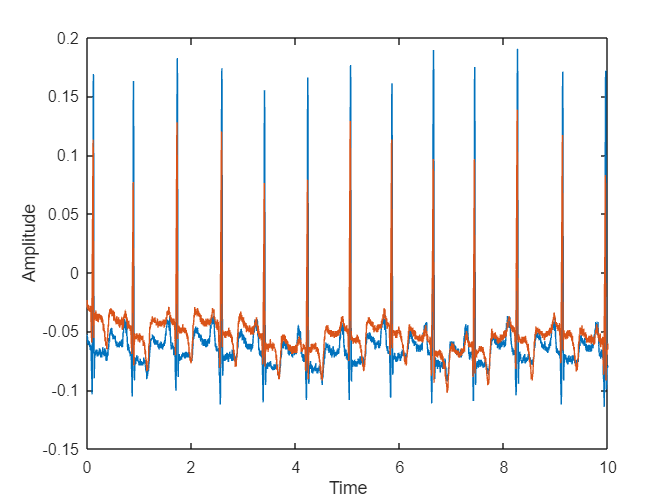

plot(t_og,a_cut)
xlabel("Time")
ylabel("Amplitude")


%encrypted mono channel waveform
t_enc=(0:length(enc_col)-1)/fs

t_enc =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


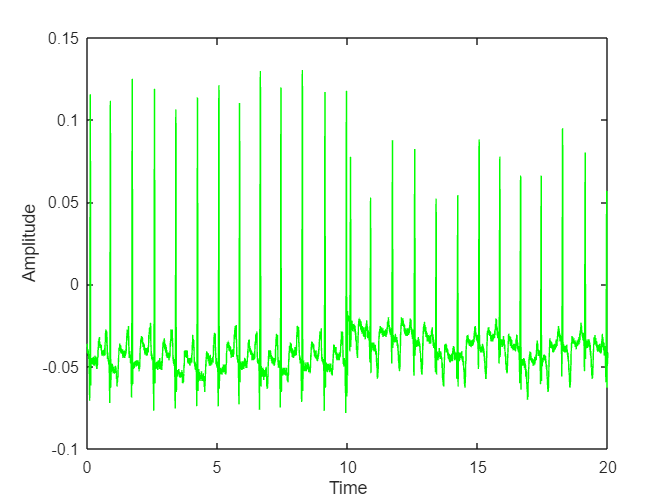

plot(t_enc,enc_col,'g')
xlabel("Time")
ylabel("Amplitude")


%decrypted 2 channel waveform
t_dec=(0:length(orig)-1)/fs

t_dec =          0    0.0028    0.0056    0.0083    0.0111    0.0139    0.0167    0.0194    0.0222    0.0250    0.0278    0.0306    0.0333    0.0361    0.0389    0.0417    0.0444    0.0472    0.0500    0.0528    0.0556    0.0583    0.0611    0.0639    0.0667    0.0694    0.0722    0.0750    0.0778    0.0806    0.0833    0.0861    0.0889    0.0917    0.0944    0.0972    0.1000    0.1028    0.1056    0.1083    0.1111    0.1139    0.1167    0.1194    0.1222    0.1250    0.1278    0.1306    0.1333    0.1361


plot(t_dec,orig)
xlabel("Time")
ylabel("Amplitude")